clear
load('data/avg_temperatures_pt2.mat')

A = (1/sqrt(17304)) * [(b_tr-mean(b_tr))/std(b_tr) (w_tr-mean(w_tr))/std(w_tr) (s_tr-mean(s_tr))/std(s_tr)];
R = A' * A

R =     0.4221    0.3999   -0.2286
    0.3999    0.4221   -0.2291
   -0.2286   -0.2291    0.4221


[v, lambda] = eig(R);
V_p = [v(:, 3) v(:,2)]

V_p =    -0.6174    0.3454
   -0.6177    0.3434
    0.4870    0.8734


T = [(b_new-mean(b_new))/std(b_new) (w_new-mean(w_new))/std(w_new) (s_new-mean(s_new))/std(s_new)]'

T =    -1.3677   -0.9201   -1.2491   -0.7097   -0.6396   -1.8424   -1.7615   -2.3548   -1.5134   -1.5889   -1.6374   -0.8877   -1.3084   -1.7885   -1.3731   -1.2491   -1.9071   -1.0711   -0.4993   -0.9686   -1.1790   -1.0495   -1.1196   -1.0333   -0.9686   -1.6860   -1.7885   -1.8855   -1.6212   -1.1196   -1.7831   -1.7345   -1.7022   -2.0689   -1.5296   -1.1142   -2.1444   -1.5565   -1.3947   -1.8586   -1.7022   -1.6105   -1.6482   -1.9017   -2.0635   -1.7399   -2.4249   -1.9880   -1.5188   -1.4109
   -1.3968   -1.0305   -1.1657   -0.5739   -0.7824   -1.7632   -1.8760   -2.4002   -1.6279   -1.8985   -1.7407   -1.2728   -1.2616   -1.6956   -1.4194   -1.2954   -1.4194   -1.2447   -0.9008   -1.1939   -1.1996   -1.1319   -1.2277   -1.1826   -0.9234   -1.1094   -1.5490   -1.6336   -1.5659   -1.1657   -1.8703   -1.4870   -1.1094   -1.7125   -1.2728   -1.1939   -1.9323   -1.3405   -0.8670   -1.0361   -1.3687   -1.3292   -1.2785   -2.0902   -1.6392   -2.3100   -2.5636   -2.2085   -2.0000   -2

alpha = V_p' * T

alpha =     2.6180    2.1407    1.8593    1.1098    1.1614    2.6795    2.8773    3.4741    2.8337    3.2934    2.9799    2.1009    2.3876    2.8418    2.4402    2.2277    2.9819    2.4680    1.8432    2.3310    2.0574    1.4778    1.4870    1.5415    1.6212    2.0858    2.4885    2.7363    2.6076    1.7031    2.2003    2.2134    1.9516    2.6524    1.9460    1.3610    2.3515    1.8349    1.5782    2.2319    2.3407    2.4124    2.7774    3.2657    2.7564    2.7589    3.0927    2.8156    2.2783    2.6910
    0.6810    1.0070   -0.1718    0.1265    0.0183   -0.4299   -0.1213   -0.6735    0.5209    0.8428    0.4393    0.6309    0.5502    0.0377    0.3216    0.3006    0.5173    1.0638    1.2729    1.0405    0.2361   -0.5170   -0.7414   -0.4528    0.1603   -0.3186   -0.3833   -0.2026    0.0488   -0.2639   -1.3584   -0.7083   -0.5826   -0.7340   -0.5791   -0.9104   -1.7022   -0.9158   -0.4540   -0.2010   -0.2611    0.0578    0.7312    0.0608   -0.4332   -0.9319   -1.6966   -1.0436   -1.0228 

t_hat = V_p * alpha

t_hat =    -1.3813   -0.9740   -1.2074   -0.6416   -0.7108   -1.8029   -1.8185   -2.3777   -1.5698   -1.7424   -1.6882   -1.0793   -1.2842   -1.7417   -1.3956   -1.2716   -1.6625   -1.1565   -0.6985   -1.0799   -1.1888   -1.0910   -1.1742   -1.1082   -0.9456   -1.3979   -1.6689   -1.7595   -1.5932   -1.1427   -1.8277   -1.6113   -1.4063   -1.8912   -1.4016   -1.1548   -2.0398   -1.4492   -1.1312   -1.4475   -1.5355   -1.4695   -1.4624   -1.9954   -1.8516   -2.0254   -2.4955   -2.0989   -1.7600   -1.8463
   -1.3833   -0.9765   -1.2075   -0.6421   -0.7111   -1.8027   -1.8189   -2.3772   -1.5715   -1.7449   -1.6898   -1.0810   -1.2858   -1.7424   -1.3969   -1.2728   -1.6643   -1.1592   -0.7015   -1.0825   -1.1897   -1.0904   -1.1731   -1.1077   -0.9464   -1.3978   -1.6687   -1.7598   -1.5940   -1.1426   -1.8256   -1.6104   -1.4056   -1.8904   -1.4009   -1.1533   -2.0370   -1.4479   -1.1307   -1.4476   -1.5355   -1.4703   -1.4645   -1.9963   -1.8514   -2.0242   -2.4929   -2.0975   -1.7585 

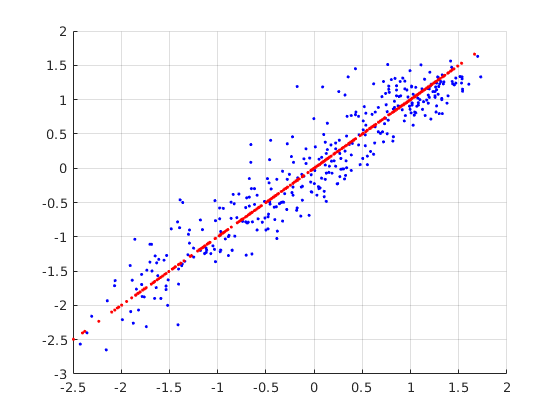

clf
hold on
plot3(T(1,:), T(2,:), T(3,:), 'b.')
plot3(t_hat(1,:), t_hat(2,:), t_hat(3,:), 'r.')
grid on

clear
clf
load('data/classdata_train.mat')
load('data/classdata_test.mat')